# Data Classification using Fisheriris Dataset

## Load the data

load fisheriris.mat

## Get species

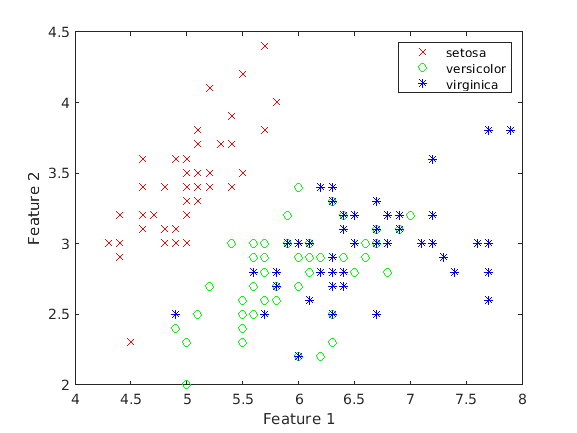

[~, ~, s] = unique(species);
figure(1);
plot(meas(s==1,1), meas(s==1,2), 'rx');
hold on
plot(meas(s==2,1), meas(s==2,2), 'go');
plot(meas(s==3,1), meas(s==3,2), 'b*');
xlabel("Feature 1");
ylabel("Feature 2");
legend("setosa", "versicolor", "virginica");

## Define Uniform sampling grid

[X,Y] = meshgrid(4:0.01:8, 2:0.01:4.5);

## Classify Data

cls = my_iris_classifier([X(:), Y(:)]);

## Create classification contour

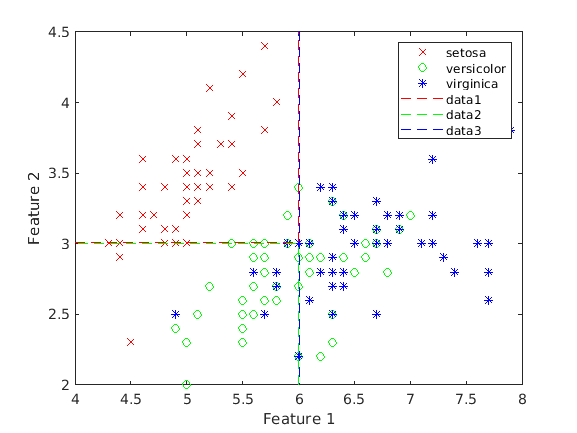

cls = reshape(cls, size(X));
contour(X,Y,cls==1, [1,1], 'r--')
contour(X,Y,cls==2, [1,1], 'g--')
contour(X,Y,cls==3, [1,1], 'b--')

## Get Percentage of Correctly Satisfied

cls = my_iris_classifier(meas);
sum(cls==s)/length(s)*100

ans = 74

## Improving the Classification Result using PCA

[~, D_pca] = pca(meas);
figure(2)
plot(D_pca(s==1,1), D_pca(s==1,2),'rx');
hold on
plot(D_pca(s==2,1), D_pca(s==2,2),'go');
plot(D_pca(s==3,1), D_pca(s==3,2),'b*');
xlabel("PCA feature 1");
ylabel("PCA feature 2");
legend("setosa", "versicolor", "virginica");
axis equal
[X,Y] = meshgrid(-4:0.01:4, -2:0.01:2);
cls = my_iris_PCA_classifier([X(:), Y(:)]);
cls = reshape(cls, size(X));
contour(X,Y,cls==1, [1,1], 'r--')
contour(X,Y,cls==2, [1,1], 'g--')
contour(X,Y,cls==3, [1,1], 'b--')
cls = my_iris_PCA_classifier(D_pca(:,1:2));
sum(cls==s)/length(s)*100

ans = 96

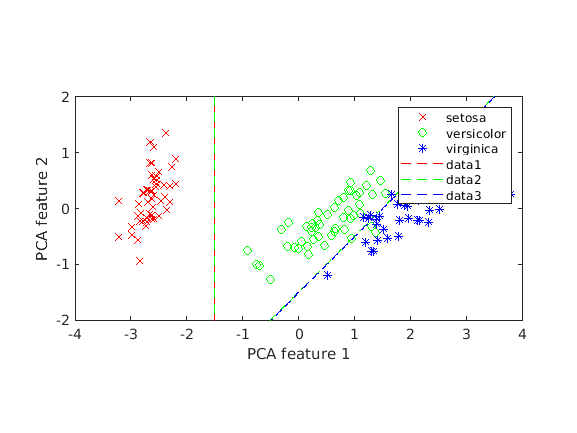

hold off

## Using Kmeans classifier(Unsupervised)

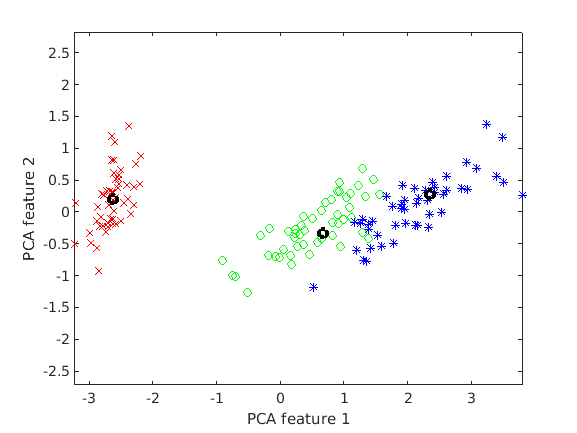

figure(3)
plot(D_pca(s==1,1), D_pca(s==1,2),'rx');
hold on
plot(D_pca(s==2,1), D_pca(s==2,2),'go');
plot(D_pca(s==3,1), D_pca(s==3,2),'b*');
xlabel("PCA feature 1");
ylabel("PCA feature 2");
axis equal
rng(0)
[cls, C] = kmeans(D_pca(:,1:2), 3);
plot(C(:,1), C(:,2), 'ko', "LineWidth", 3);

## Finding the distance using Euclidean Distance

% Euclidean distance is the square root of the sum of squared differences across each dimension
dist1 = sqrt((C(1,1)-X).^2 + (C(1,2)-Y).^2);
dist2 = sqrt((C(2,1)-X).^2 + (C(2,2)-Y).^2);
dist3 = sqrt((C(3,1)-X).^2 + (C(3,2)-Y).^2);

### Classification

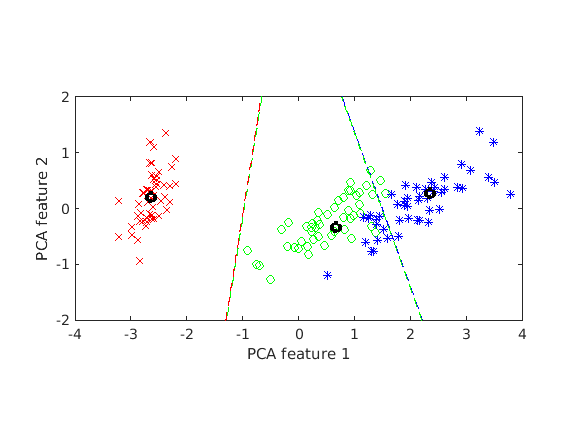

cls1 = ((dist1<dist2) & (dist1<dist3));
cls2 = (~cls1 & (dist2<dist3));
cls3 = (~cls1 & ~cls2);
contour(X,Y,cls1, [1,1], 'b--')
contour(X,Y,cls2, [1,1], 'g--')
contour(X,Y,cls3, [1,1], 'r--')
hold off

sum(cls==s)/length(s)*100 %Class is reveresed so it needs to be sorted

ans = 31.3333

sum(4-cls==s)/length(s)*100

ans = 88.6667

## K-Means (suppervised)

figure(4)
C = [mean(D_pca(s==1,:));mean(D_pca(s==2,:));mean(D_pca(s==3,:))];
plot(D_pca(s==1,1), D_pca(s==1,2),'rx');
hold on
plot(D_pca(s==2,1), D_pca(s==2,2),'go');
plot(D_pca(s==3,1), D_pca(s==3,2),'b*');
axis equal
plot(C(:,1), C(:,2), 'mo', "LineWidth", 3);
% Find the distance
dist1 = sqrt((C(1,1)-X).^2 + (C(1,2)-Y).^2);
dist2 = sqrt((C(2,1)-X).^2 + (C(2,2)-Y).^2);
dist3 = sqrt((C(3,1)-X).^2 + (C(3,2)-Y).^2);
cls1 = ((dist1<dist2) & (dist1<dist3));
cls2 = (~cls1 & (dist2<dist3));
cls3 = (~cls1 & ~cls2);
contour(X,Y,cls1, [1,1], 'r--')
contour(X,Y,cls2, [1,1], 'g--')
contour(X,Y,cls3, [1,1], 'b--')
% Find the distance of D_PCA
dist1_pca = sqrt((C(1,1)-D_pca(:,1)).^2 + (C(1,2)-D_pca(:,2)).^2);
dist2_pca = sqrt((C(2,1)-D_pca(:,1)).^2 + (C(2,2)-D_pca(:,2)).^2);
dist3_pca = sqrt((C(3,1)-D_pca(:,1)).^2 + (C(3,2)-D_pca(:,2)).^2);
cls1 = ((dist1_pca<dist2_pca) & (dist1_pca<dist3_pca));
cls2 = (~cls1 & (dist2_pca<dist3_pca));
cls3 = (~cls1 & ~cls2);
%Overall classification vector
cls = 3*cls3+2*cls2+cls1;
sum(cls==s)/length(s)*100

ans = 92.6667

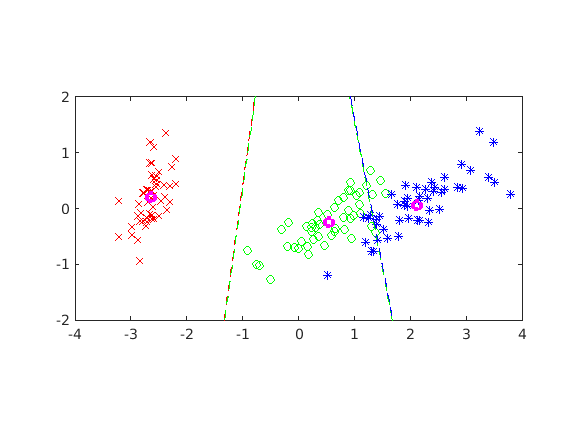

hold off

# Mahalanobis Distance

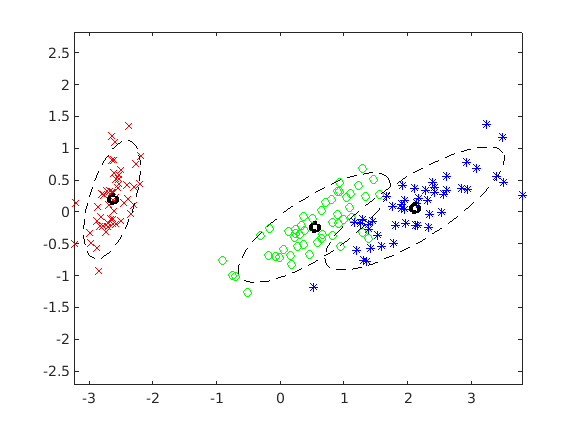

mdl = my_fitpca(D_pca(:,1:2), s);
centroid_x = mdl.class(1).mu(1);
centroid_y = mdl.class(1).mu(2);
majoraxis_x = mdl.class(1).eigvect(1,1)*2*sqrt(mdl.class(1).eigvals(1));
majoraxis_y = mdl.class(1).eigvect(1,2)*2*sqrt(mdl.class(1).eigvals(1));
minoraxis_x = mdl.class(1).eigvect(2,1)*2*sqrt(mdl.class(1).eigvals(2));
minoraxis_y = mdl.class(1).eigvect(2,2)*2*sqrt(mdl.class(1).eigvals(2));
figure(5)
plot(D_pca(s==1,1), D_pca(s==1,2),'rx');
hold on
plot(D_pca(s==2,1), D_pca(s==2,2),'go');
plot(D_pca(s==3,1), D_pca(s==3,2),'b*');
axis equal
theta = 0:pi/32:2*pi;
for i=1:3
    majoraxis_x = mdl.class(i).eigvect(1,1)*2*sqrt(mdl.class(i).eigvals(1));
    majoraxis_y = mdl.class(i).eigvect(1,2)*2*sqrt(mdl.class(i).eigvals(1));
    minoraxis_x = mdl.class(i).eigvect(2,1)*2*sqrt(mdl.class(i).eigvals(2));
    minoraxis_y = mdl.class(i).eigvect(2,2)*2*sqrt(mdl.class(i).eigvals(2));
    centroid_x = mdl.class(i).mu(1);
    centroid_y = mdl.class(i).mu(2);
    plot(centroid_x, centroid_y, 'ko', "LineWidth", 3);
    plot(centroid_x+cos(theta)*majoraxis_x+sin(theta)*minoraxis_x,centroid_y+cos(theta)*majoraxis_y+sin(theta)*minoraxis_y, 'k--');
end
hold off

### Test data

hold on
test_data = [1,1.5];
plot(test_data(1), test_data(2), 'kx', "LineWidth", 3);
cls = my_predictpca(mdl, [X(:), Y(:)]);
contour(X, Y, reshape(cls, size(X))==1,[1 1],'r--');
contour(X, Y, reshape(cls, size(X))==2,[1 1],'g--');
contour(X, Y, reshape(cls, size(X))==3,[1 1],'b--');
cls = my_predictpca(mdl, D_pca(:,1:2));
sum(cls==s)/length(s)*100

ans = 97.3333

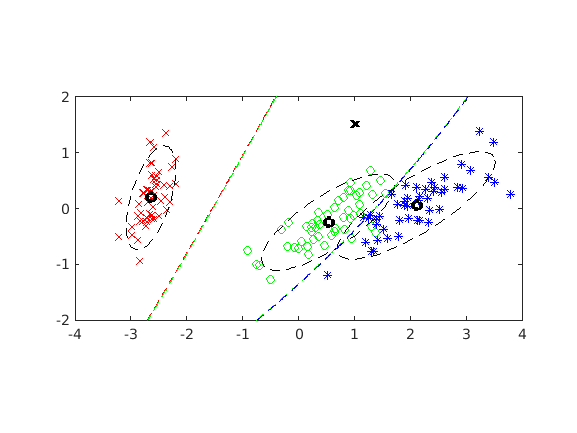

hold off

## Fitlm MATLAB function

mdl = fitlm(D_pca(:,1:2),s)

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)           2     0.020341     98.324    5.1965e-136
    x1              0.37711    0.0099253     37.995      6.626e-78
    x2             -0.18837      0.04143    -4.5467     1.1305e-05


Number of observations: 150, Error degrees of freedom: 147
Root Mean Squared Error: 0.249
R-squared: 0.909,  Adjusted R-Squared: 0.908
F-statistic vs. constant model: 732, p-value = 3.72e-77

cls = round(predict(mdl, D_pca(:, 1:2)));
sum(cls==s)/length(s)*100

ans = 96.6667

# SVM(suppervised) only support binary classification

figure(6)
plot(D_pca(s==1,1), D_pca(s==1,2),'rx');
hold on
plot(D_pca(s==2,1), D_pca(s==2,2),'go');
plot(D_pca(s==3,1), D_pca(s==3,2),'b*');
axis equal
traindata = D_pca(1:2:end,1:2);
traincls = s(1:2:end);
mdl = my_fitsvm(traindata, traincls, 0.75);
pdct = my_predictsvm(mdl, traindata);
sum(pdct == traincls)/length(traincls)*100

ans = 96

testdata = D_pca(2:2:end, 1:2);
testcls = s(2:2:end);
pdct = my_predictsvm(mdl, testdata);
sum(pdct == testcls)/length(testcls)*100

ans = 97.3333

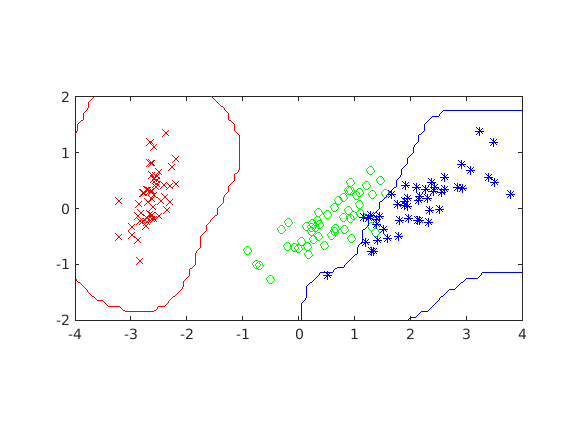

%define meshgrid with step size of 0.1
[X, Y] = meshgrid(-4:.1:4,-2:.1:2);
cls = my_predictsvm(mdl, [X(:), Y(:)]);
cls = reshape(cls, size(X));
contour(X, Y, cls, [1.5 1.5], 'r');
contour(X, Y, cls, [2.5 2.5], 'b');
hold off